# Velocity-Curvature Optimization For A designScenario Track

#### Reset the workspace to default to prevent issues in variable referencing and plotting

clear
clf

#### Begin timer to track running time of script

timerOverall = tic;
fprintf(['Beginning Script...' newline]);

Beginning Script...


#### Select track for use given a list of provided tracks

[scenario, testName, trackWidth] = silverstoneTest;

#### The below Boolean Controls determine whether or not to output video/GIF files as a part of the script running

NOTE: Opting for these video outputs will likely increase the running-time of the script significantly

video1 = false; % Video of optimization by each iteration
video2 = false; % Video of optimization by point for EACH iteration
video3 = false; % Video of velocity profile execution in real-time
formationGIF = true; % Animation of path optimization process

#### Next, we can extract bounds of the path from drivingScenario scenario. These bounds are then split into outer and inner bounds (2 nx2 [X,Y] matrices), in-between each point is a centerpoint (nx2 matrix). These centerpoints are used to estimate the distance in-between each as well as the distance of the overall track at a given point

bounds = roadBoundaries(scenario);

outerBounds = flip(bounds{1}(:,1:2),1);
innerBounds = bounds{2}(:,1:2);
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));

centersDiff = [0; sqrt(sum((centers(2:end,:)-centers(1:end-1,:)).^2,2))];
sVals = cumsum(centersDiff);

#### This normalizing factor aims to scale all points on the track such that the overall track length is a whole number. This factor is then applied to the bounds as well as the centerpoints

normFactor = floor(sVals(end))/sVals(end);

innerBoundsNormalized = innerBounds.*normFactor;
centersNormalized = centers.*normFactor;
outerBoundsNormalized = outerBounds.*normFactor;
sValsNormalized = sVals.*normFactor;

#### Waypoints are extracted from the centerpoints by spline interpolation at set distances of 1m between each waypoint. Outer and inner bounds are also extracted by spline interpolation to create a nx4 matrixc of [X, Y, X, Y] points

waypoints = [spline(sValsNormalized, centersNormalized(:,1),0:ceil(trackWidth/3):sValsNormalized(end))',...
             spline(sValsNormalized, centersNormalized(:,2),0:ceil(trackWidth/3):sValsNormalized(end))'];

boundaryPointsNormalized = [spline(sValsNormalized, innerBoundsNormalized(:,1), 0:ceil(trackWidth/3):sValsNormalized(end))',...
                            spline(sValsNormalized, innerBoundsNormalized(:,2), 0:ceil(trackWidth/3):sValsNormalized(end))',...
                            spline(sValsNormalized, outerBoundsNormalized(:,1), 0:ceil(trackWidth/3):sValsNormalized(end))',...
                            spline(sValsNormalized, outerBoundsNormalized(:,2), 0:ceil(trackWidth/3):sValsNormalized(end))'];

#### The waypoints, normalized track width, maximum iterations, minimum dk, acceptable rise, and the name of the test are passed into the waypoint curvature optimizer. This optimizer returns a set of new waypoints with optimized curvature as well as cell arrays for each iteration's points (Video Set 1) and each point's shift in each iteration (Video Set Point). It also returns the new path's overall length. A timer is also started to track how long the optimizer takes to meet the ending criteria. See discreteWaypointOptimizer.m for more information

fprintf(['Beginning Optimization...' newline])

Beginning Optimization...


timeOptimization = tic;
maxIterations = 10; % Maximum iterations to run
mindK = 0.005; % Minimum dK before returning optimized points
riseAllowance = 10; % Allowable rise in total curvature (due to patternsearch overshoot)
bufferSize = 0.2; % Proportion of tracl alocated to being buffer zones
[waypointsFit, videoSet, videoSetPt] = discreteWaypointOptimizer(waypoints, normFactor*trackWidth, maxIterations, mindK, riseAllowance, bufferSize, testName);

Iteration: 1 | k: 35.91926759
Iteration: 2 | k: 30.84580059
Iteration: 3 | k: 29.46949116
Iteration: 4 | k: 28.97807627
Iteration: 5 | k: 28.78904704
Iteration: 6 | k: 28.67915013
Iteration: 7 | k: 28.64050360
Iteration: 8 | k: 28.52153527
Iteration: 9 | k: 28.52684213
Iteration: 10 | k: 28.62187162


fprintf(['Optimization Complete: %f sec' newline],toc(timeOptimization));

Optimization Complete: 161.968365 sec


#### Reset the points to be un-normalized by dividing the columns within the cell arrays by the normalizing factor used previously.

videoSet(:,1) = cellfun(@(x) x/normFactor, videoSet(:,1), 'un',0);
videoSetPt(:,1) = cellfun(@(x) x/normFactor, videoSetPt(:,1), 'un',0);

videoSet(:,3) = cellfun(@(x) x/normFactor, videoSet(:,3), 'un',0);
videoSetPt(:,3) = cellfun(@(x) x/normFactor, videoSetPt(:,3), 'un',0);

waypointsFit = waypointsFit./normFactor;

#### A dt value, the new, un-normalized list of waypoints, number of laps, maximum tangential force, maximum normal force, and mass of the vehicle are passed to the velocity profiler. The profiler returns the velocity profile of the mass [velocity, time, distance traveled, x, y, ft, fn, lap] and the velocity profile by distance traveled, including critical velocities [v, s, vCrit]. A set of data is also returned for the middle-most lap, which is considered the "best" lap. A timer is also started to track how long it takes to calculate the velocity profile

fprintf(['Beginning Velocity Profiling...' newline])

Beginning Velocity Profiling...


timeVelocity = tic;
dt = 0.001; % Time step for profiling in seconds
lapQty = 3; % Number of laps to run
ftMax = 15000; % Maximum tangential force in N
fnMax = 5000; % Maximum normal force in N
vMax = 60; % Maximum velocity in terms of m/s
mass = 300; % Mass in kg
[velocityProfile, velocityProfileByS, bestLapSet] = velocityProfiler(dt, waypointsFit, lapQty, ftMax, fnMax, vMax, mass);

467 Profiles Identified
25 Profiles Generated
50 Profiles Generated
75 Profiles Generated
100 Profiles Generated
125 Profiles Generated
150 Profiles Generated
175 Profiles Generated
200 Profiles Generated
225 Profiles Generated
250 Profiles Generated
275 Profiles Generated
300 Profiles Generated
325 Profiles Generated
350 Profiles Generated
375 Profiles Generated
400 Profiles Generated
425 Profiles Generated
450 Profiles Generated
Beginning Time-Velocty Calculations...
Time-Velocity Calculations Complete: 120.636877 sec


fprintf(['Velocity Profiling Complete: %f sec' newline], toc(timeVelocity));

Velocity Profiling Complete: 132.344470 sec


#### Minimum time for a lap is determined based on the time values within the middle-most lap of the velocity profile

minTLap = bestLapSet(end,2) - bestLapSet(1,2);

#### The number of iterations and final curvature are extracted from the Video Set data

iterationEnd = videoSet{end,2};
curvatureEnd = videoSet{end,3};

#### If desired, the below four if statements determine whether or not to create video output. Video 1 is a video of the optimization by iteration; this shows how the track changes over each iteration. Video 2 is a video of the optimization by point; this shows how the track changes over each point within each iteration (this will take a long time). Video 3 is a video of the velocity profile in real-time; this shows how the point mass travels within the path along theh optimized trajectory. The GIF is a general creation animation that shows the track, followed by adding its centerpoints, followed by adding the chords along which the points are optimized, and ending with it displaying each iteration's path similar to Video 1.

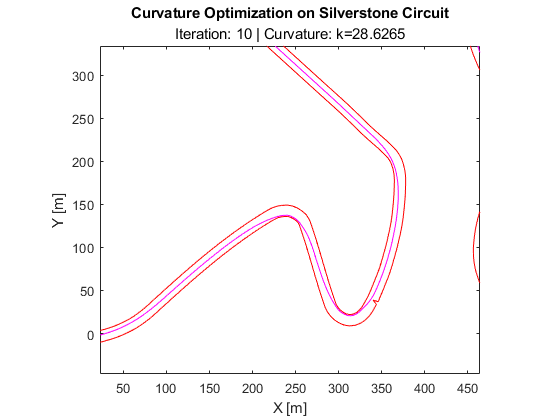

Beginning GIF Output...


GIF Complete: 4.230124 sec


if video1
    fprintf(['Beginning Video Output By Iteration...' newline]);
    timeVideo1 = tic;
    writer1(videoSet, testName, centers, innerBounds, outerBounds);
    fprintf(['Iteration Video Complete: %f sec' newline],toc(timeVideo1));
end

if video2
    fprintf(['Beginning Video Output By Point...' newline]);
    timeVideo2 = tic;
    writer2(videoSetPt, testName, centers, innerBounds, outerBounds);
    fprintf(['Point Video Complete: %f sec' newline],toc(timeVideo2));
end

if video3
    fprintf(['Beginning Video Output By Velocity...' newline]);
    timeVideo3 = tic;
    writer3(velocityProfile, 40, testName, waypointsFit, innerBounds, outerBounds, minTLap, iterationEnd, curvatureEnd);
    timeVideo3Out = toc(timeVideo3);
    fprintf(['Velocity Video Complete: %f sec' newline],timeVideo3Out);
end

if formationGIF
    fprintf(['Beginning GIF Output...' newline]);
    timeGIF = tic;
    gifWriter(videoSet, testName, boundaryPointsNormalized/normFactor, trackWidth, bufferSize)
    timeGIFOut = toc(timeGIF);
    fprintf(['GIF Complete: %f sec' newline],timeGIFOut);
end

#### This plots the final, optimized path as well as a scatter plot that is color-coded based on velocity at each point. This velocity is then put into a color bar to give viewers a reference of what the optimal velocity path looks like without the video animation. It is then saved to a PNG 

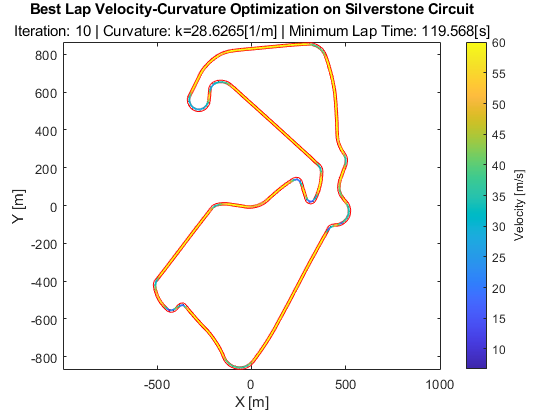

plot(centers(:,1), centers(:,2), ':k',...
    outerBounds(:,1), outerBounds(:,2), 'r',...
    innerBounds(:,1), innerBounds(:,2), 'r',...
    waypointsFit(:,1), waypointsFit(:,2), 'm',...
    'Visible',"on");
hold on
scatter(bestLapSet(:,3), bestLapSet(:,4), 3, bestLapSet(:,1),'filled');
colormap('parula');
colBar = colorbar('eastoutside');
colBar.Label.String = "Velocity [m/s]";
xlabel('X [m]');
ylabel('Y [m]');
title(['Best Lap Velocity-Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{end,2}),' | Curvature: k=',num2str(videoSet{end,3}), '[1/m] | Minimum Lap Time: ',num2str(minTLap), '[s]']);
axis equal;
hold off;
imwrite(frame2im(getframe(gcf)), ['velocityGradientBestLap', testName(testName ~= ' '), '.png']);

#### This plots the velocity profile as a function of the distance traveled across the track's laps. It is an alternate visualization of the velocity profile similarly output

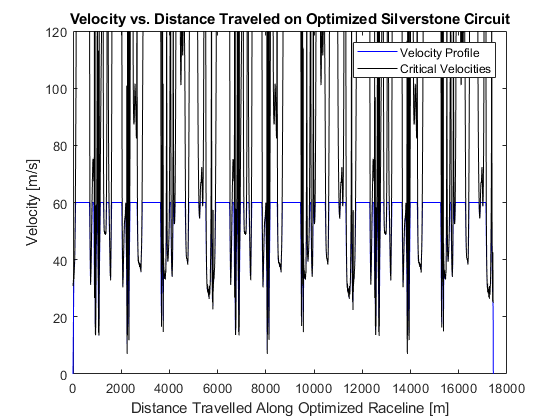

plot(velocityProfileByS(:,1), velocityProfileByS(:,2), 'b',...
     velocityProfileByS(:,1), velocityProfileByS(:,3), 'k');
hold on
xlabel('Distance Travelled Along Optimized Raceline [m]');
ylabel('Velocity [m/s]');
title(['Velocity vs. Distance Traveled on Optimized ', testName]);
legend({'Velocity Profile', 'Critical Velocities'},'Location',"northeast");
ylim([0, vMax*2]);
hold off
imwrite(frame2im(getframe(gcf)), ['velocityByDistance', testName(testName ~= ' '), '.png']);

#### Timing is concluded and output to show how long the overall script 

fprintf(['Script Complete: %f sec' newline], toc(timerOverall))

Script Complete: 303.050117 sec


function writer1(videoSet, testName, centers, innerBounds, outerBounds)
clf;
writer = VideoWriter(testName(testName ~= ' '));
writer.FrameRate = 1;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer2(videoSet, testName, centers, innerBounds, outerBounds)
clf;
writer = VideoWriter([testName(testName ~= ' '),'ByPt']);
writer.FrameRate = 60;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    plot(videoSet{idxVidSet,4}(1), videoSet{idxVidSet,4}(2),'*m');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer3(videoSet, fps, testName, minCurPath, innerBounds, outerBounds, minTLap, itEnd, kEnd)
clf;
writer = VideoWriter([testName(testName ~= ' '),'ByVel']);
writer.FrameRate = fps;
skipFactor = (1/fps)*(1/(videoSet(2,2)-videoSet(1,2)));
open(writer);
for idxVidSet = 1:skipFactor:size(videoSet,1)
    plot(minCurPath(:,1), minCurPath(:,2), ':k',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet(idxVidSet,4), videoSet(idxVidSet,5), 'mo',...
        'Visible',"on");
    hold on
    title(['Velocity Optimization on Minimum Curvature Path for ',testName],['Iteration: ',num2str(itEnd,'%.0f'),' | Curvature: k=',num2str(kEnd),'[1/m] | Minimum Lap Time t=',num2str(minTLap,'%.3f'),'[s]', newline,'Time: t=',num2str(videoSet(idxVidSet,2),'%.3f'),'[s] | Velocity: v=',num2str(videoSet(idxVidSet,1),'%.3f'), '[m/s] | Lap: L=',num2str(videoSet(idxVidSet,8),'%.0f')]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function gifWriter(videoSet, testName, inOutBounds, trackWidth, bufferSize)
clf;
halfTrackWidth = (trackWidth/2)*(1-bufferSize);
fileName = [testName(testName ~= ' '), '.gif'];
plot(inOutBounds(:,1), inOutBounds(:,2), 'r',...
     inOutBounds(:,3), inOutBounds(:,4), 'r');
title(['Curvature Optimization on ',testName],['Iteration: 0 | Curvature: k=0.000']);
xlabel('X [m]');
ylabel('Y [m]');
axis equal;
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','LoopCount',Inf,'DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['emptyTrack', testName(testName ~= ' '), '.png']);
hold on
plot(videoSet{1,1}(:,1), videoSet{1,1}(:,2), ' *m', 'MarkerSize', 1);
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['trackWaypoints', testName(testName ~= ' '), '.png']);
for idxWP = 1:length(videoSet{1,1})-1
    angTemp = atan2(videoSet{1,1}(idxWP+1,2)-videoSet{1,1}(idxWP,2), videoSet{1,1}(idxWP+1,1)-videoSet{1,1}(idxWP,1));   
    rotLinePoints = [0, (-halfTrackWidth); 0, (halfTrackWidth)]*[cos(-angTemp) -sin(-angTemp); sin(-angTemp) cos(-angTemp)]+[videoSet{1,1}(idxWP,1), videoSet{1,1}(idxWP,2)];
    plot([rotLinePoints(2,1), rotLinePoints(1,1)], [rotLinePoints(2,2), rotLinePoints(1,2)],"LineWidth",0.3,'Marker','none');
end
[gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',1);
imwrite(frame2im(getframe(gcf)), ['waypointChords', testName(testName ~= ' '), '.png']);
hold off

for idxVidSet = 1:size(videoSet,1)
    plot(inOutBounds(:,1), inOutBounds(:,2), 'r',...
        inOutBounds(:,3), inOutBounds(:,4), 'r');
    hold on
    for idxWP = 1:length(videoSet{1,1})-1
        angTemp = atan2(videoSet{1,1}(idxWP+1,2)-videoSet{1,1}(idxWP,2), videoSet{1,1}(idxWP+1,1)-videoSet{1,1}(idxWP,1));
        rotLinePoints = [0, (-halfTrackWidth); 0, (halfTrackWidth)]*[cos(-angTemp) -sin(-angTemp); sin(-angTemp) cos(-angTemp)]+[videoSet{1,1}(idxWP,1), videoSet{1,1}(idxWP,2)];
        plot([rotLinePoints(2,1), rotLinePoints(1,1)], [rotLinePoints(2,2), rotLinePoints(1,2)],"LineWidth",0.3,'Marker','none');
    end
    plot(videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    [gifFrame,colorMap] = rgb2ind(frame2im(getframe(gcf)),256);
    imwrite(gifFrame,colorMap,fileName,'gif','WriteMode','append','DelayTime',0.25);
end
imwrite(frame2im(getframe(gcf)), ['waypointFinal', testName(testName ~= ' '), '.png']);
end